# 04 HO: Thermal Conduction

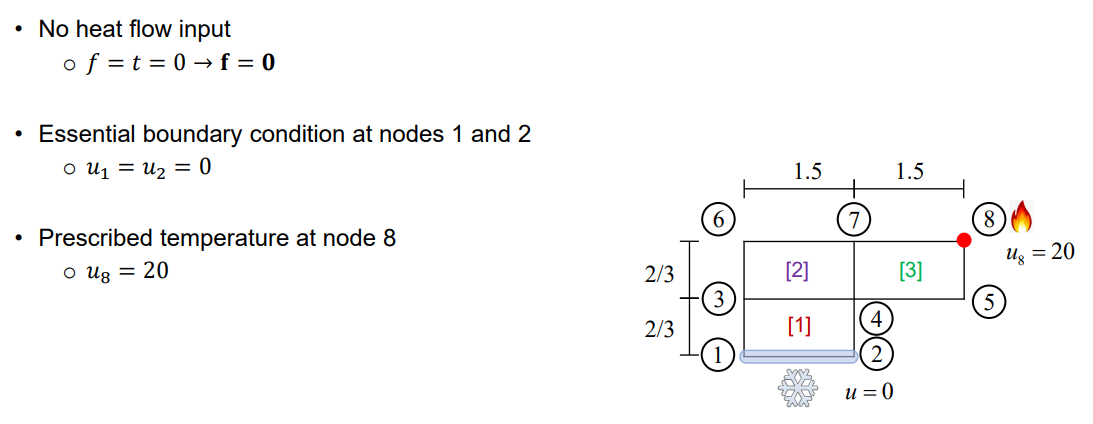

clear all; close all; clc

% MODEL
%  6   --   7   --   8
%  |        |        |
%  |   2    |   3    |
%  3   --   4   --   5
%  |        |
%  |   1    | 
%  1   --   2
%
% ELEMENT
%  4   --   3 
%  |        |
%  |        | 
%  1   --   2

% Given parameters
lx = 1.5;
ly = 2/3;
k = 500;

% Set up nodes and elements
nodes = [0, 0;
         lx, 0;
         0, ly;
         lx, ly;        % Locations of the
         2*lx, ly;      %  8 GLOBAL nodes
         0, 2*ly;       
         lx, 2*ly;
         2*lx, 2*ly];

nNodes = size(nodes, 1);
dofPerNode = 1;

% GLOBAL nodes for each element (counterclockwise)
elements = [1 2 4 3;    % element 1
            3 4 7 6;    % element 2
            4 5 8 7];   % element 3

nElements = size(elements, 1);
dofPerElement = dofPerNode * size(elements, 2); % dofPerNode * NodesPerElement

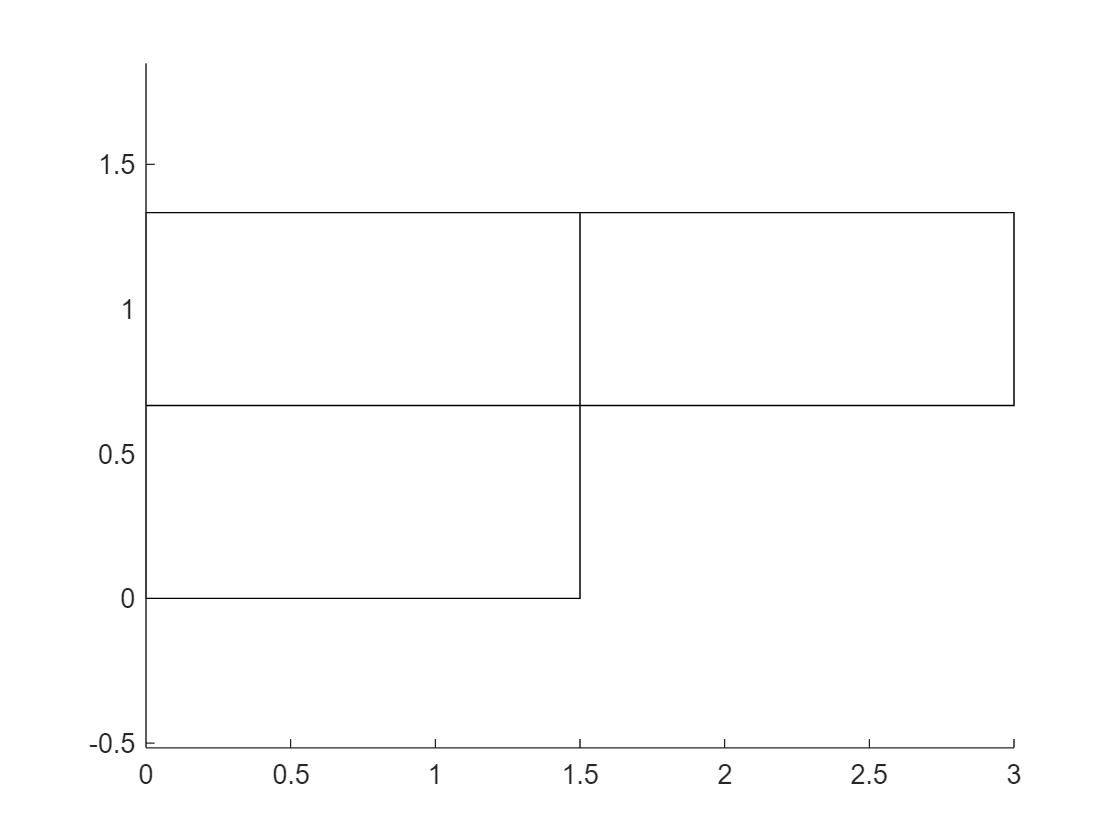

% Optional: Plot structure
f1 = figure; axis equal;
p = plotElements(nodes, elements);

% Set up system matrices
K = zeros(nNodes * dofPerNode);
u = zeros(nNodes * dofPerNode, 1);
f = zeros(nNodes * dofPerNode, 1);

% Integrate stiffness by looping over elements
[xg, wg] = gaussianPoints2D(); % second order & 2d
for e = 1 : nElements
    KE = zeros(dofPerElement);
    % fE = zeros(dofPerElement, 1);

    xmin = nodes(elements(e, 1), 1);
    xmax = nodes(elements(e, 2), 1);
    ymin = nodes(elements(e, 1), 2);
    ymax = nodes(elements(e, 4), 2);

    % Integrate stiffness using Gauss quadrature
    for g = 1 : size(xg, 1)
        % Map integration point from standard space (r, s) to cartesian coordinates (x, y)
        xgi(1) = 0.5 * (xmax - xmin) * xg(g,1) + ...
                 0.5 * (xmin + xmax);
        xgi(2) = 0.5 * (ymax - ymin) * xg(g,2) + ...
                 0.5 * (ymin + ymax);

        % Evaluate shape function gradients at integration point b
        dh = shapeFunctionGradients(xmin, xmax, ymin, ymax, xgi);   % xgi

        % Evaluate summand for quadrature of element stiffness matrix
        KE = KE + k * (dh' * dh);
    end

    % Mapping from xy to rs space
    KE = (xmax - xmin) / 2 * ...
         (ymax - ymin) / 2 * ...
         KE;

    % Use element connectivity to add element stiffness to global stiffness matrix
    K(elements(e, :), elements(e, :)) = K(elements(e, :), elements(e, :)) + KE;
end

% Prescribed temperature on node 8
u(8) = 20;
f = f - u(8) * K(:, 8);

% Solve system
fixeddofs = [1, 2, 8];
freedofs = setdiff(1 : 8, fixeddofs);

u(freedofs) = K(freedofs, freedofs) \ f(freedofs)

u =          0
         0
    0.6701
    4.6158
   16.3954
    1.5445
    5.0193
   20.0000


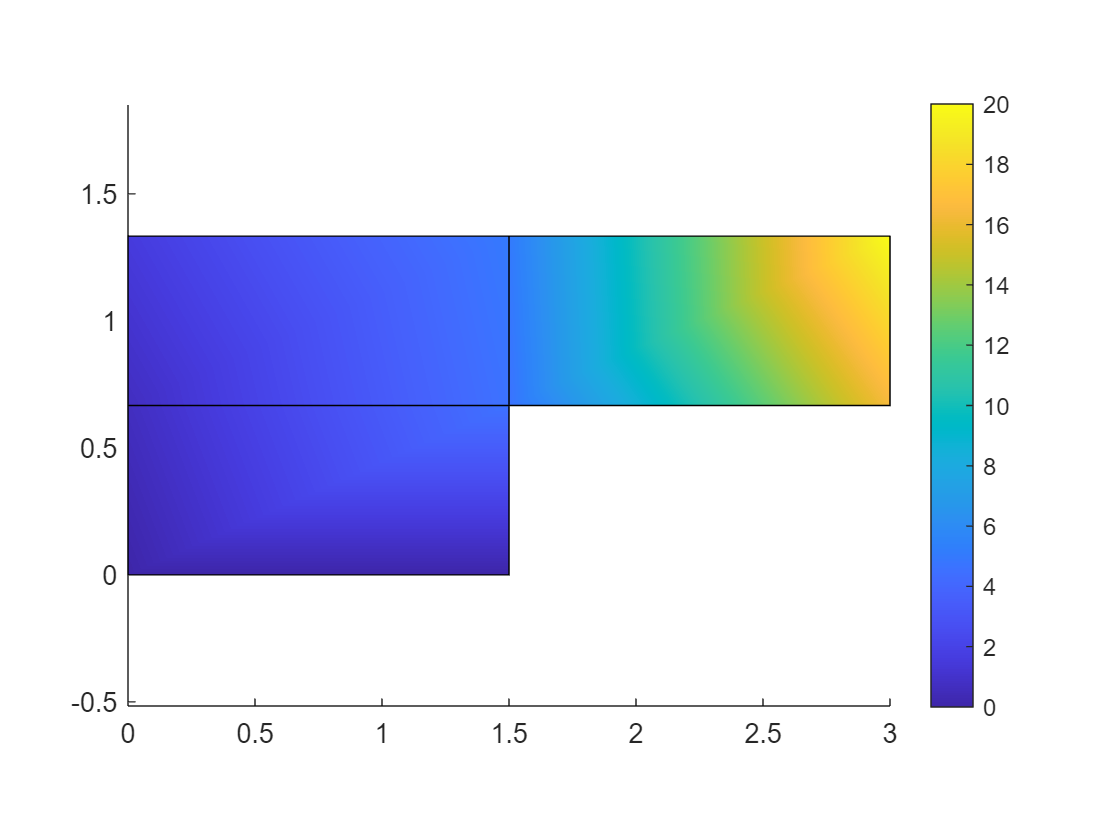

% Plot temperature field per patch by letting Matlab interpolate between nodal variables
for e = 1 : nElements
    p(e).set('FaceColor', 'interp', 'FaceVertexCData', u(elements(e, :)));
end
colorbar;

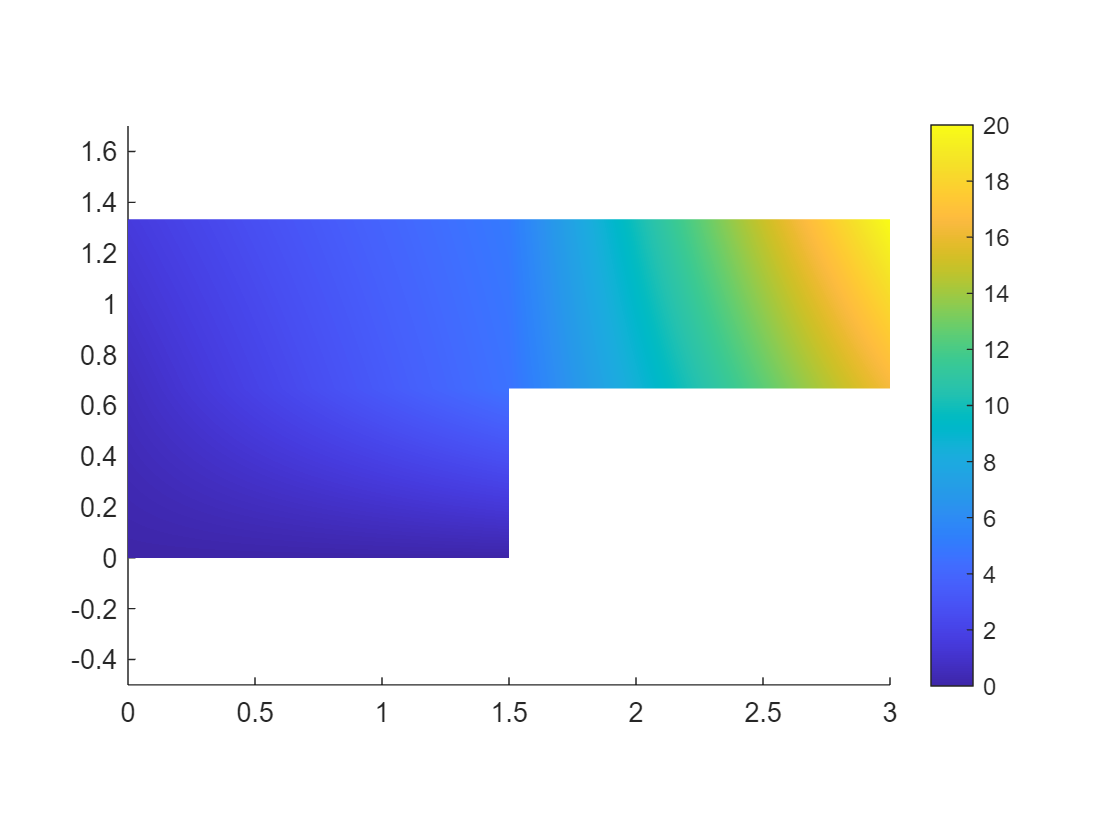

%{
    Superposition of shape functions
%}

% Plot temperature field per element ue = sum (h_i * ue_i)
figure; axis equal;
hold on;
colorbar;
for e = 1 : nElements
    xmin = nodes(elements(e, 1), 1);
    xmax = nodes(elements(e, 2), 1);
    ymin = nodes(elements(e, 1), 2);
    ymax = nodes(elements(e, 4), 2);  
    fhDisplacement = @(x, y) displacementField(u(elements(e, :)), xmin, xmax, ymin, ymax, x, y);
    fsurf(fhDisplacement, [xmin xmax ymin ymax], 'LineStyle', 'none');
end
xlim([0 3])
ylim([-0.5 1.7])
hold off;
view(2);

## Additional functions

function h = shapeFunctions(xmin, xmax, ymin, ymax, x)
    %{
        Evaluate shape functions for rectangular element at x in cartesian coordinates
        INPUT
          xmin (scalar)       Minimum x coordinate for element
          xmax (scalar)       Maximum x coordinate for element
          ymin (scalar)       Minimum y coordinate for element
          ymax (scalar)       Maximum y coordinate for element
          x (array)           Point(s) for evaluation of shape functions in cartesian coordinates
    %}

    A = (xmax - xmin) * (ymax - ymin);

    % Evaluate shape functions
    h(:, 1) = 1/A * (xmax - x(:, 1)) .* (ymax - x(:, 2));
    h(:, 2) = 1/A * (x(:, 1) - xmin) .* (ymax - x(:, 2));
    h(:, 3) = 1/A * (x(:, 1) - xmin) .* (x(:, 2) - ymin);
    h(:, 4) = 1/A * (xmax - x(:, 1)) .* (x(:, 2) - ymin);
end

function dh = shapeFunctionGradients(xmin, xmax, ymin, ymax, x)
    %{
        Evaluate shape function gradients for rectangular element at x in cartesian coordinates
        INPUT
          xmin (scalar)       Minimum x coordinate for element
          xmax (scalar)       Maximum x coordinate for element
          ymin (scalar)       Minimum y coordinate for element
          ymax (scalar)       Maximum y coordinate for element
          x (array)           Point(s) for evaluation of shape functions in cartesian coordinates
    %}

    A = (xmax - xmin) * (ymax - ymin);

    dh(1:2, 1) = -1/A * [(ymax - x(2)) ; (xmax - x(1))];
    dh(1:2, 2) =  1/A * [(ymax - x(2)) ; (-(x(1) - xmin))];
    dh(1:2, 3) =  1/A * [(x(2) - ymin) ; ((x(1) - xmin))];
    dh(1:2, 4) = -1/A * [(x(2) - ymin) ; -(xmax - x(1))];
end

function uOut = displacementField(u, xmin, xmax, ymin, ymax, x, y)
    %{
        Compute state variable u from nodal variables, interpolated using shape functions
        INPUT
          u (array)       Nodal variables for element in local order
          xmin (scalar)   Minimum x coordinate for element
          xmax (scalar)   Maximum x coordinate for element
          ymin (scalar)   Minimum y coordinate for element
          ymax (scalar)   Maximum y coordinate for element
          x (array)       x coordinate(s) for evaluation of u
          y (array)       y coordinate(s) for evaluation of u
        OUTPUT
          uout (array)    Variable u for given x and y in element
    %}

    uOut = zeros(size(x));
    h = shapeFunctions(xmin, xmax, ymin, ymax, [x(:), y(:)]);
    for i = 1 : numel(x)
        uOut(i) = h(i, :) * u;
    end
end

function p = plotElements(nodes, elements)
    %{
        Plot elements by plotting a patch for each element
        INPUT
          nodes (array)       Nodal coordinates as (nNodes x 2) array
          elements (array)    Nodal indices per element as (nElements x 4) array
        OUTPUT
          p (array)           Patches for elements
    %}

    hold on;
    for e = 1 : size(elements, 1)
        elementNodes = nodes(elements(e, :), :);    % gets the element nodes coordinates
        p(e) = patch(elementNodes(:, 1), elementNodes(:, 2), 'w');
    end
    hold off;
end